# Pohlhoussen Solution for Flow over a Cylinder

% Geometry
r = 1; 
y = (0:0.01:5);

% Constants
Uinf = 1;
rho = 1;
nu = 1;
mu = 1;

% Symbolic Potential Flow Solution

syms x R
Ue = 2*Uinf * (x/R - 1/factorial(3)*(x/R)^3 + 1/factorial(5)*(x/R)^5 - 1/factorial(7)*(x/R)^7);

dUe = diff(Ue,x);
dUe_2 = diff(dUe,x);

% Stagnation Values
Ko = 0.0770;
Shape_factor = 7.052;
dz_0 = -0.0652/(dUe)^2 * dUe_2;
% dUe_m = 2/R - x^2/R^3 + x^4/(12*R^5) - x^6/(360*R^7)

% Integration Method

del_x = 0.001;
X = (del_x:del_x:10);

Fk(1) = 0.47   -6*Ko;
mo_sym = sqrt((nu*Ko)/dUe);
z = mo_sym^2/nu;
R = r;
x = X(1);
z = eval(subs(z));

dz = Fk(1)/Ue;
R = r;
x = X(1);
dz = eval(subs(dz));
dz_0 = eval(subs(dz_0));
z = z+dz_0*X(1);


% Plotting
% Kplot = (-0.12:del_x:0.09);
% Fplot = 0.47 - 6*Kplot;
% 
% figure
% plot(Kplot,Fplot)


% Stepping Process

for i =1:1900
    
    x = X(i);
    R = r;
    Ue_new =  (2*x) / R - x^3/(3*R^3) + x^5/(60*R^5) - x^7/(2520*R^7);
    dUe_new =  2/R - x^2/R^3 + x^4/(12*R^5) - x^6/(360*R^7);
    
    delz = Fk(i)/Ue_new *del_x;
    K_new = (z + delz)*dUe_new;
    
    ji = -16;
    jii = 16;
    
    k = 1;
    fix = 2;
    
    if i >1870
        tol = 0.01;
        ji = -20;
        jii = -10;
    else
        tol = 0.00001;
    end
    jj = 1;
    while fix > tol && jj<1e5
        if k == 1
            k_low_guess = (37/315 - 1/945 *ji - 1/9072 * ji^2)^2 * ji;
            ki = k_low_guess;
            
            k_high_guess = (37/315 - 1/945*jii - 1/9072 * jii^2)^2 * jii;
            kii = k_high_guess;
            
            k = k+1;
        else
            jii = ((jii-ji)/(kii-ki)) *(K_new - ki)+ ji;
            
            k_guess = (37/315 - 1/945*jii - 1/9072 * jii^2)^2 * jii;
            kii = k_guess;
            fix = abs(K_new - kii);
            k = k+1;
        end
        jj = jj+1;
    end
    SF = jii;
    K_new = kii;
       
    mo(i) = sqrt((nu*K_new)/dUe_new);
    
    del(i) = mo(i)/(1/63*(37/5 - SF/15-SF^2/144));
    
    eta(i,:) = y./del(i);
    
    del_s(i) = del(i) * (3/10-SF/120);
    
    tau(i) = mu * Ue_new/del(i)* (2+SF/6);
    
    
    u_Ue(i,:) = (2*eta(i,:) - 2*eta(i,:).^3 + eta(i,:).^4) + SF/6 .*(eta(i,:) - 3*eta(i,:).^2 + 3*eta(i,:).^3-eta(i,:).^4);
    
    Fk(i+1) = 2* (37/315 - SF/945-SF^2/9072) * (2 - 116/315*SF + ((2/945 +1/120) *SF^2) + 2/9072*SF^3);
    
    z = z + delz;
    
end


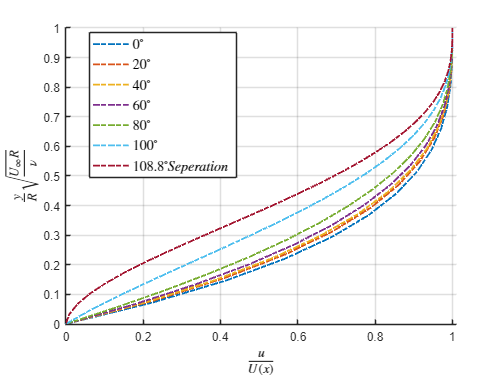

% Final Plots    

angle = X(1:length(tau))*180/pi;
anglefind = [0.05 20 40 60 80 100 106.9];
tol = 0.02;
figure
grid on
hold on 
for i = 1:length(anglefind)
    line = find(abs(angle-anglefind(i))<tol);
    plot(u_Ue(line,(1:15:end)),eta(line,(1:15:end)),'-.','linewidth',1.5)
end
xlim([0 1.01])
ylim([0 1])
legend('$0^{\circ}$','$20^{\circ}$','$40^{\circ}$','$60^{\circ}$','$80^{\circ}$','$100^{\circ}$','$108.8^{\circ} Seperation$','interpreter','latex','location','best','fontsize',12);
hXLabel = xlabel('$\frac{u}{U(x)}$','interpreter','latex');
hYLabel = ylabel('$\frac{y}{R} \sqrt{\frac{U_{\infty} R}{\nu}}$','interpreter','latex');

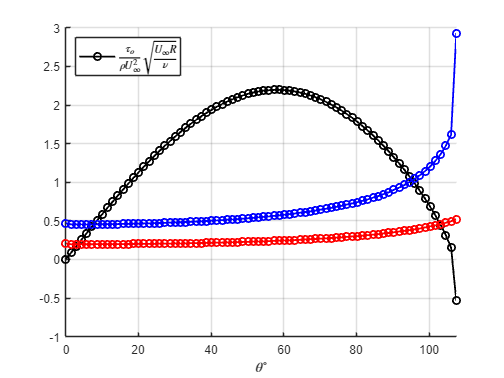

pltangle = angle(1:length(tau));

figure 
hold on
plot(pltangle(1:25:end-20),tau(1:25:end-20),'-o','Color','k','linewidth',1.5)
plot(pltangle(1:25:end-20),del_s(1:25:end-20),'-o','color','b','linewidth',1.5)
plot(pltangle(1:25:end-20),mo(1:25:end-20),'-o','color','r','linewidth',1.5)
xlim([0 max(pltangle(1:25:end))])
xlabel('$\theta^{\circ}$','interpreter','latex','fontsize',12)
%ylabel('$\frac{\tau_o}{\rho U_{\infty}^2} \sqrt{\frac{U_{\infty} R}{\nu}}$','interpreter','latex')
legend('$\frac{\tau_o}{\rho U_{\infty}^2} \sqrt{\frac{U_{\infty} R}{\nu}}$','interpreter','latex', Location="northwest")
% '$\frac{\delta_1}{R U_{\infty}^2} \sqrt{\frac{U_{\infty} R}{\nu}}$',...'$\frac{\delta_2}{R U_{\infty}^2} \sqrt{\frac{U_{\infty} R}{\nu}}
grid on


% figure
% plot(pltangle(1:25:end-20),tau(1:25:end-20),'-o','Color','k','linewidth',1.5)
% xlim([0 max(pltangle(1:25:end))])
% grid on
% xlabel('$\frac{u}{U(x)}$','interpreter','latex')    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
    
